# Plotting Data

This is really cool data that is very valueable and could be worth just as much as your first born child

mf4files

User selected C:\Users\schro\Downloads\BAJA_TRACK_4_15\00000435\00000001.MF4


User selected C:\Users\schro\OneDrive\Documents\GitHub\CAN-Tools\Scripts\Can Data reading\mf4 plot data\DEV1_4_13.dbc


Pulls all captured data from a MF4 file utilizing the most recent DBC

## Plotting Temps from TMS

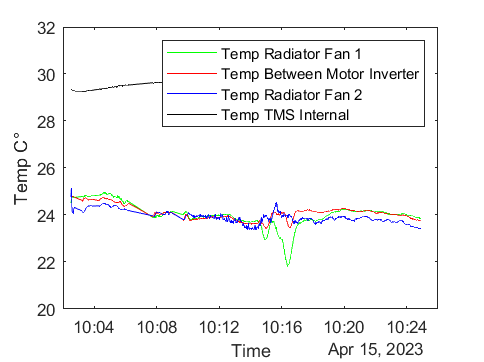

figure(1)
plot(N8_TPDO0.Time, N8_TPDO0.Temp_Radiator_Fan_1/100, "green")
hold on
plot(N8_TPDO0.Time, N8_TPDO0.Temp_Between_Motor_Inverter/100, "red")
plot(N8_TPDO0.Time, N8_TPDO0.Temp_Radiator_Fan_2/100, "blue")
plot(N8_TPDO0.Time, N8_TPDO0.Temp_TMS_Internal/100, "black")
hold off
xlim("auto")
ylim("auto")
legend(["Temp Radiator Fan 1","Temp Between Motor Inverter","Temp Radiator Fan 2", "Temp TMS Internal"])

xlabel("Time")
ylabel("Temp C" + char(176))

## Duty Cycle Plots

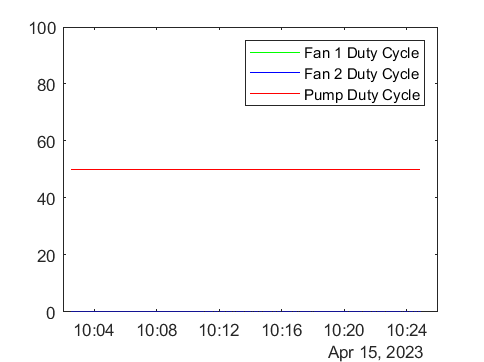

figure(2)
plot(N8_TPDO1.Time, N8_TPDO1.Fan_1_Duty_Cycle, "green")
hold on
ylim([0 100])
plot(N8_TPDO1.Time, N8_TPDO1.Fan_2_Duty_Cycle, "blue")
plot(N8_TPDO1.Time, N8_TPDO1.Pump_Duty_Cycle, "red")
legend(["Fan 1 Duty Cycle","Fan 2 Duty Cycle","Pump Duty Cycle"])
hold off

## BMS Pack Temps 22

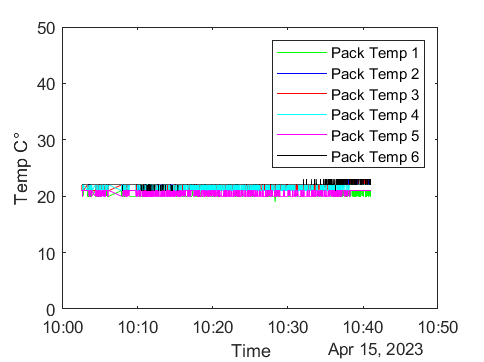

figure(3)

plot(N22_TPDO2.Time, N22_TPDO2.BMS_Pack_Temp_1, "green")
hold on
ylim([0 50])
plot(N22_TPDO2.Time, N22_TPDO2.BMS_Pack_Temp_2, "blue")
plot(N22_TPDO2.Time, N22_TPDO2.BMS_Pack_Temp_3, "red")
plot(N22_TPDO2.Time, N22_TPDO2.BMS_Pack_Temp_4, "cyan")
plot(N22_TPDO2.Time, N22_TPDO2.BMS_Pack_Temp_5, 'm')
plot(N22_TPDO2.Time, N22_TPDO2.BMS_Pack_Temp_6, "black")
hold off
xlabel("Time")
ylabel("Temp C" + char(176))
legend(["Pack Temp 1","Pack Temp 2","Pack Temp 3","Pack Temp 4","Pack Temp 5","Pack Temp 6"])

## BMS Board Temps 22

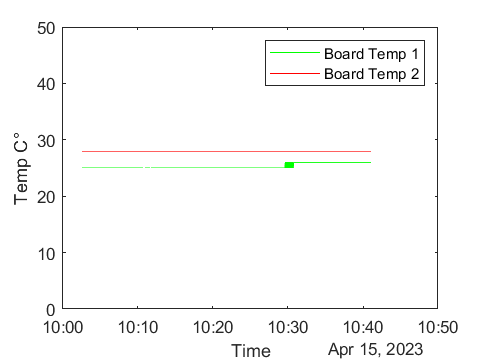

figure(4)
plot(N22_TPDO2.Time, N22_TPDO2.BMS_Board_Temp_1, "green")
hold on 
ylim([0 50])
plot(N22_TPDO2.Time, N22_TPDO2.BMS_Board_Temp_2, "red")
hold off
xlabel("Time")
ylabel("Temp C" + char(176))
legend(["Board Temp 1","Board Temp 2"])

## BMS Pack Temps 23

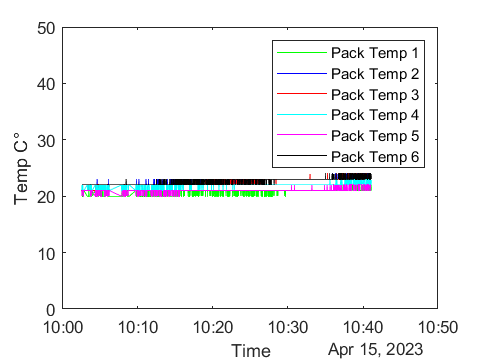

figure(4)

plot(N23_TPDO2.Time, N23_TPDO2.BMS_Pack_Temp_1, "green")
hold on
ylim([0 50])
plot(N23_TPDO2.Time, N23_TPDO2.BMS_Pack_Temp_2, "blue")
plot(N23_TPDO2.Time, N23_TPDO2.BMS_Pack_Temp_3, "red")
plot(N23_TPDO2.Time, N23_TPDO2.BMS_Pack_Temp_4, "cyan")
plot(N23_TPDO2.Time, N23_TPDO2.BMS_Pack_Temp_5, 'm')
plot(N23_TPDO2.Time, N23_TPDO2.BMS_Pack_Temp_6, "black")
hold off
xlabel("Time")
ylabel("Temp C" + char(176))
legend(["Pack Temp 1","Pack Temp 2","Pack Temp 3","Pack Temp 4","Pack Temp 5","Pack Temp 6"])

## BMS Board Temps 23

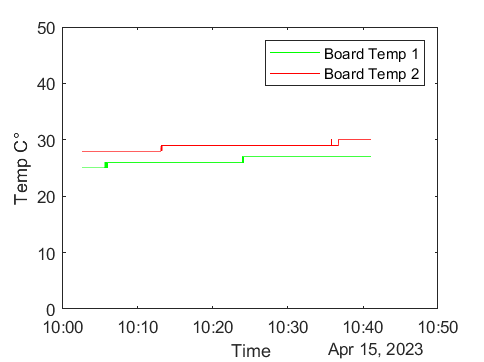

figure(6)
plot(N23_TPDO2.Time, N23_TPDO2.BMS_Board_Temp_1, "green")
hold on 
ylim([0 50])
plot(N23_TPDO2.Time, N23_TPDO2.BMS_Board_Temp_2, "red")
hold off
xlabel("Time")
ylabel("Temp C" + char(176))
legend(["Board Temp 1","Board Temp 2"])

## Pack 2 Voltage

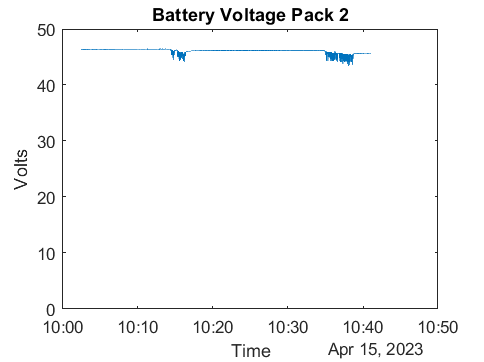

plot(N22_TPDO0.Time, N22_TPDO0.BMS_Battery_Voltage/1000)
ylim([0 50])

title("Battery Voltage Pack 2")
xlabel("Time")
ylabel("Volts")

## Pack 3 Voltage

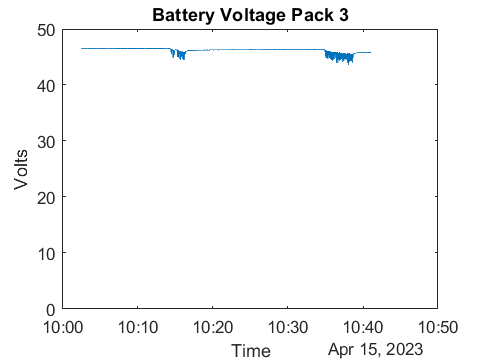

plot(N23_TPDO0.Time, N23_TPDO0.BMS_Battery_Voltage/1000)
ylim([0 50])

title("Battery Voltage Pack 3")
xlabel("Time")
ylabel("Volts")

## Pack 2 Status

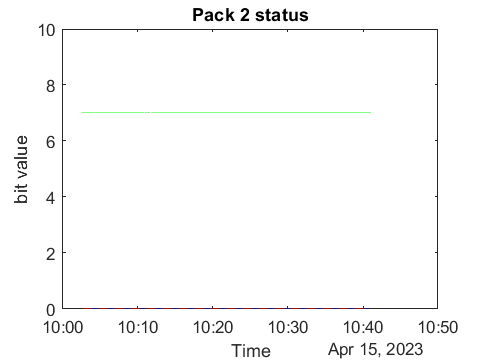

plot(N22_TPDO3.Time, N22_TPDO3.Battery_Status, "green")
ylim([0,10])
hold on
plot(N22_TPDO3.Time, N22_TPDO3.I2C_ERR, "blue")
plot(N22_TPDO3.Time, N22_TPDO3.BQ_Comm_Err, "red", "LineStyle","--")
plot(N22_TPDO1.Time, N22_TPDO1.BMS_State, "green")
hold off
title("Pack 2 status")
xlabel("Time")
ylabel("bit value")

## Pack 3 Status

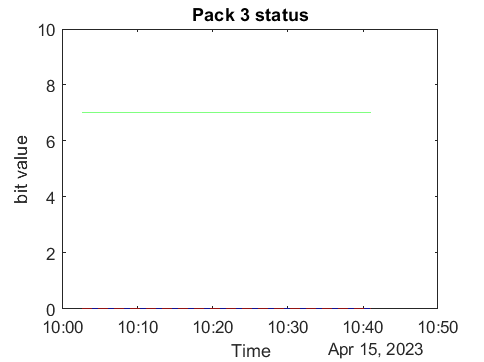

plot(N23_TPDO3.Time, N23_TPDO3.Battery_Status, "green")
ylim([0,10])
hold on
plot(N23_TPDO3.Time, N23_TPDO3.I2C_ERR, "blue")
plot(N23_TPDO3.Time, N23_TPDO3.BQ_Comm_Err, "red", "LineStyle","--")
plot(N23_TPDO1.Time, N23_TPDO1.BMS_State, "green")
hold off
title("Pack 3 status")
xlabel("Time")
ylabel("bit value")